数值分析第三章

标准开头

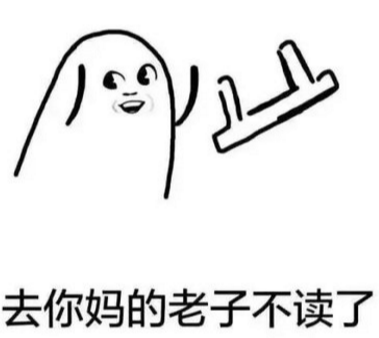

第一题

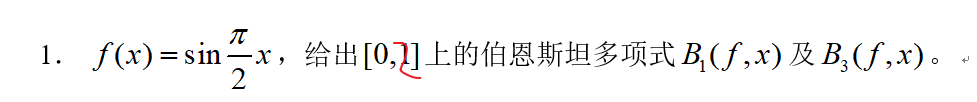

计算公式

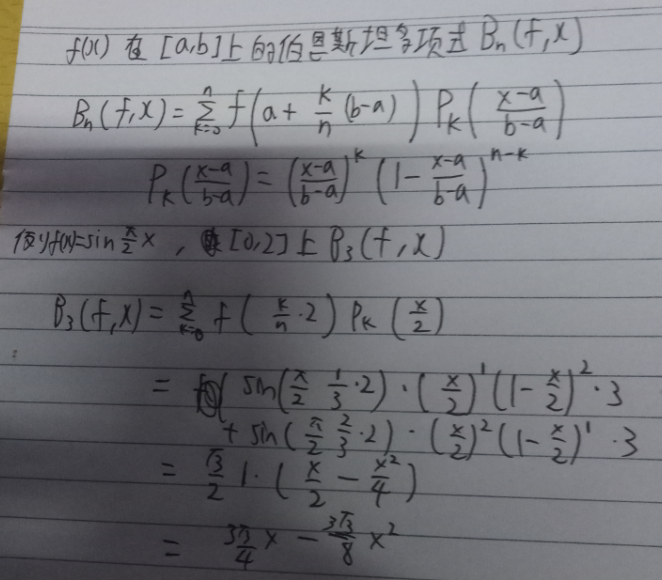

接下来做个简单的伯恩斯坦多项式

clear;
syms x;
n=3;%伯恩斯坦多项式系数
f=sin(pi/2*x) %第一题方程

$$f = \sin\left(\frac{\pi \,x}{2}\right)$$

span=[0,2]; %采样范围
X=span(1):(span(2)-span(1))/n:span(2); %采样范围
f=0;
for k=0:n
    variable=sin(pi/2*X(k+1))*nchoosek(n,k);
    if abs(variable)<10^(-10)
        variable=0;
    end
    f=f+variable*(x/2)^k*(1-x/2)^(n-k);
end
f

$$f = \frac{3\,\sqrt{3}\,x\,{\left(\frac{x}{2}-1\right)}^{2}}{4}-\frac{3\,\sqrt{3}\,x^{2}\,\left(\frac{x}{2}-1\right)}{8}$$

f=simplify(f)%化简位符合要求

$$f = -\frac{3\,\sqrt{3}\,x\,\left(x-2\right)}{8}$$

f=collect(f);
f=vpa(f,6)%最终答案,保留6位有效数字

$$f = 1.29904\,x-0.649519\,x^{2}$$

但是这个算法很奇怪,怎么可能连f(2)都没用上呢,应该是先一步变换

f(t)=f(x/2)=

第四题

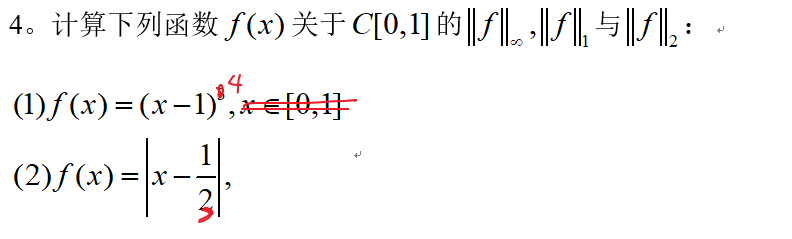

计算方法

clear;
syms x;
f=(x-1)^4;
%fm=@(x)(-(x-1)^4);
%fm(fminbnd(fm,0,1))
%matlab最大值计算很不好，还是得自己算
L1=int(abs(f),0,1)%L1范数

$$L1 = \frac{1}{5}$$

L2=(int(abs(f)^2,0,1))^0.5%L2范数

$$L2 = \frac{1}{3}$$

clear;
syms x;
f=abs(x-1/3);
%最大值自己算
L1=int(abs(f),0,1)%L1范数

$$L1 = \frac{5}{18}$$

L2=(int(abs(f)^2,0,1))^0.5%L2范数

$$L2 = \frac{1}{3}$$

第八题

计算方法

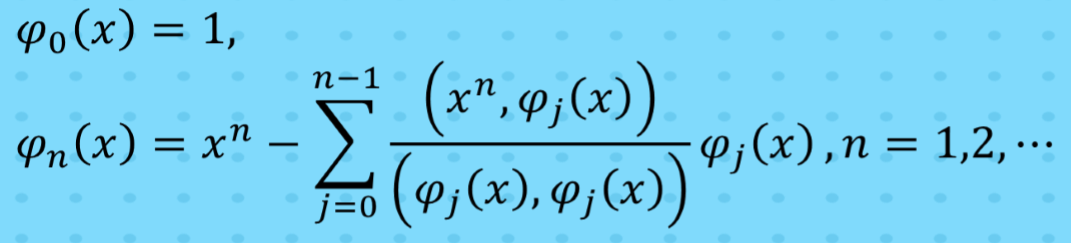

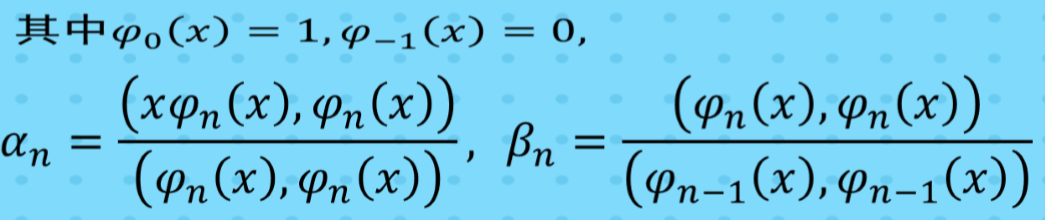

clear;
syms x;
n=3;
g=cell(n,1);%φ
a=cell(n,1);%递推公式系数a
b=cell(n,1);%递推公式系数b
rou=2+x^2

$$rou = x^{2}+2$$

g{1}=1;%φ0=1
g{2}=x;%φ1=x
a{3}=int(rou*x*g{2}*g{2},-1,1)/int(rou*g{2}*g{2},-1,1);
b{3}=int(rou*g{2}*g{2},x,-1,1)/int(rou*g{1}*g{1},x,-1,1);%第一位为函数,第二位为函数变量,3是下限,4是上限
g{3}=(x-a{3})*g{2}-b{3}*g{1};
banner=sprintf("第%d正交多项式是\n%s",3-1,collect(g{3}));
disp(banner)%显示结果

第2正交多项式是
x^2 - 13/35


接下来是一直计算到n

for k=3:n+1
    a{k}=int(rou*x*g{k-1}*g{k-1},-1,1)/int(rou*g{k-1}*g{k-1},x,-1,1);
    banner=sprintf("a%d是%s",k-1,collect(a{k}));
    disp(banner)%显示结果
    b{k}=int(rou*g{k-1}*g{k-1},x,-1,1)/int(rou*g{k-2}*g{k-2},x,-1,1);%第一位为函数,第二位为函数变量,3是下限,4是上限
    banner=sprintf("b%d是%s",k-1,collect(b{k}));
    disp(banner)%显示结果
    g{k}=(x-a{k})*g{k-1}-b{k}*g{k-2};
    banner=sprintf("第%d正交多项式是",k-1);
    disp(banner)%显示结果
    disp(collect(g{k}))
end

a2是0


b2是13/35


第2正交多项式是


$$x^{2}-\frac{13}{35}$$

a3是0


b3是116/455


第3正交多项式是


$$x^{3}-\frac{57\,x}{91}$$

第十一题

计算方法

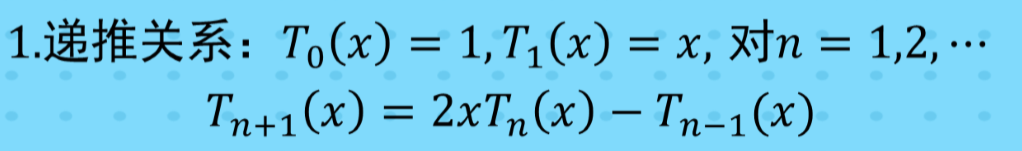

clear;
syms x;
n=3;%
T3=4*x^3-3*x

$$T3 = 4\,x^{3}-3\,x$$

t=zeros(n,1);%零点
for k=1:n %求零点
    t(k)=vpa(cos((2*k-1)/2/n*pi),10);%vpa提高精度
    if abs(t(k))<10^(-10)
        t(k)=0;
    end
end
t=sort(t)%其实答案是-sqrt(3)/2,0,-sqrt(3)/2这里面有精度问题

t =    -1170/1351  
       0       
    1170/1351  


Y=exp(1).^(2.*t)

Y =      739/4177  
       1       
    4177/739   


p=Lagrange(t,Y)

ans = '长成这幅鬼样子: '

$$p = 2.55277\,x^{2}+3.16117\,x+1.0$$

$$p = 2.55277\,x^{2}+3.16117\,x+1.0$$

误差计算方法

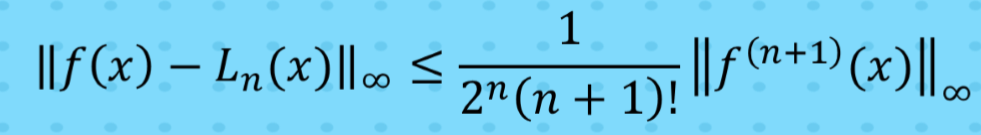

diff(exp(2*x),x,3)/8/3%误差,x=1时为最大值,也就是e^2/3

$$ans = \frac{{\mathrm{e}}^{2\,x}}{3}$$

第十二题

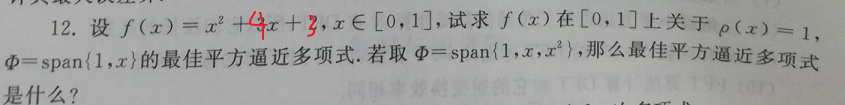

计算方法

clear;
syms x;
f=x^2+4*x+3;
rou=1;
n=2%正交基个数

n =        2       


%正交基φ
fai=cell(2,1);
fai{1}=1;
fai{2}=x;
%法方程左边的矩阵
A=zeros(n);
b=zeros(1,n)';
for i=1:n
    b(i)=int(rou*f*fai{i},x,0,1);
    for j=1:n
        A(i,j)=int(rou*fai{i}*fai{j},x,0,1);
    end
end
disp(A)

       1              1/2     
       1/2            1/3     



disp(b)%输出结果会略写,请点击下面图标显示全部结果,比如b2是37/12,不点只会显示37/1

      16/3     
      37/12    



disp(A^(-1)*b)%第一问的解,分别是正交基从前往后的系数,比如这里答案是17/6+5x

      17/6     
       5       



第二小问

clear;
syms x;
f=x^2+4*x+3;
rou=1;
n=3;%正交基个数
%正交基φ
fai=cell(n,1);
fai{1}=1;
fai{2}=x;
fai{3}=x^2;
%法方程左边的矩阵
A=zeros(n);
b=zeros(1,n)';
for i=1:n
    b(i)=int(rou*f*fai{i},x,0,1);
    for j=1:n
        A(i,j)=int(rou*fai{i}*fai{j},x,0,1);
    end
end
disp(A)

       1              1/2            1/3     
       1/2            1/3            1/4     
       1/3            1/4            1/5     



disp(b)%输出结果会略写,请点击下面图标显示全部结果,比如b2是37/12,不点只会显示37/1

      16/3     
      37/12    
      11/5     



disp(A^(-1)*b)%第二问的解,分别是正交基从前往后的系数

       3       
       4       
       1       



第十三题

clear;
syms x;
f=x^3;
rou=1;
n=3;%正交基个数
%正交基φ
fai=cell(n,1);
fai{1}=1;
fai{2}=x;
fai{3}=x^2;
%法方程左边的矩阵
A=zeros(n);
b=zeros(1,n)';
for i=1:n
    b(i)=int(rou*f*fai{i},x,0,1);
    for j=1:n
        A(i,j)=int(rou*fai{i}*fai{j},x,0,1);
    end
end
disp(A)

       1              1/2            1/3     
       1/2            1/3            1/4     
       1/3            1/4            1/5     



disp(b)%输出结果会略写,请点击下面图标显示全部结果,比如b2是37/12,不点只会显示37/1

       1/4     
       1/5     
       1/6     



disp(A^(-1)*b)%第二问的解,分别是正交基从前往后的系数

       1/20    
      -3/5     
       3/2     



第十四题

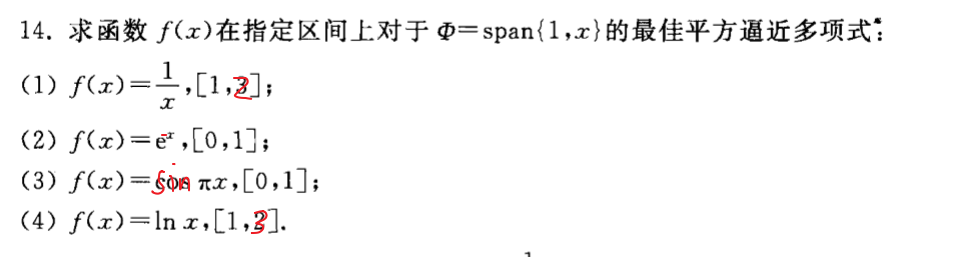

第一问

clear;
syms x;
f=1/x;
up=2;%积分上限
lb=1;%积分下限

ZuiJiaPingFangPoly(f, lb, up);

法方程左边的矩阵
    1.0000    1.5000
    1.5000    2.3333

法方程右边列向量


$$\left(\begin{array}{c} \log\left(2\right)\\ 1 \end{array}\right)$$

多项式系数,分别是1和x的系数


$$\left(\begin{array}{c} 28\,\log\left(2\right)-18\\ 12-18\,\log\left(2\right) \end{array}\right)$$

化简后的结果


$$ans = \left(\begin{array}{c} 28\,\log\left(2\right)-18\\ 12-18\,\log\left(2\right) \end{array}\right)$$

显示小数


$$ans = \left(\begin{array}{c} 1.4081210556784686636824994008289\\ -0.47664925007901556951017818624718 \end{array}\right)$$

第二问

clear;
syms x;
f=exp(-x);
up=1;%积分上限
lb=0;%积分下限

ZuiJiaPingFangPoly(f, lb, up);

法方程左边的矩阵
    1.0000    0.5000
    0.5000    0.3333

法方程右边列向量


$$\left(\begin{array}{c} 1-{\mathrm{e}}^{-1}\\ 1-2\,{\mathrm{e}}^{-1} \end{array}\right)$$

多项式系数,分别是1和x的系数


$$\left(\begin{array}{c} 8\,{\mathrm{e}}^{-1}-2\\ 6-18\,{\mathrm{e}}^{-1} \end{array}\right)$$

化简后的结果


$$ans = \left(\begin{array}{c} 8\,{\mathrm{e}}^{-1}-2\\ 6-18\,{\mathrm{e}}^{-1} \end{array}\right)$$

显示小数


$$ans = \left(\begin{array}{c} 0.94303552937153857276419016129169\\ -0.6218299410859617887194278629063 \end{array}\right)$$

第三问

clear;
syms x;
f=sin(pi*x);
up=1;%积分上限
lb=0;%积分下限

ZuiJiaPingFangPoly(f, lb, up);

法方程左边的矩阵
    1.0000    0.5000
    0.5000    0.3333

法方程右边列向量


$$\left(\begin{array}{c} \frac{2}{\pi }\\ \frac{1}{\pi } \end{array}\right)$$

多项式系数,分别是1和x的系数


$$\left(\begin{array}{c} \frac{2}{\pi }\\ 0 \end{array}\right)$$

化简后的结果


$$ans = \left(\begin{array}{c} \frac{2}{\pi }\\ 0 \end{array}\right)$$

显示小数


$$ans = \left(\begin{array}{c} 0.63661977236758134307553505349006\\ 0 \end{array}\right)$$

由于matlab的sin函数非常弱智,所有需要进一步测试

a=zeros(2,1);
a(1)=int(1*f,x,0,1)

a =     0.6366
         0


vpa(int(1*f,x,0,1))

$$ans = 0.63661977236758134307553505349006$$

a(2)=int(x*f,x,0,1)

a =     0.6366
    0.3183


vpa(int(x*f,x,0,1))

$$ans = 0.31830988618379067153776752674503$$

tmp=([1 0.5;0.5 1/3]^(-1))*a

tmp =     0.6366
    0.0000


vpa(tmp(2),6)%给x的系数保留6位有效数字

$$ans = 2.06409e-17$$

第四问

clear;
syms x;
f=log(x);
up=3;%积分上限
lb=1;%积分下限

ZuiJiaPingFangPoly(f, lb, up);

法方程左边的矩阵
    2.0000    4.0000
    4.0000    8.6667

法方程右边列向量


$$\left(\begin{array}{c} \log\left(27\right)-2\\ \frac{9\,\log\left(3\right)}{2}-2 \end{array}\right)$$

多项式系数,分别是1和x的系数


$$\left(\begin{array}{c} \frac{13\,\log\left(27\right)}{2}-\frac{27\,\log\left(3\right)}{2}-7\\ \frac{27\,\log\left(3\right)}{4}-3\,\log\left(27\right)+3 \end{array}\right)$$

化简后的结果


$$ans = \left(\begin{array}{c} \log\left(729\right)-7\\ 3-\frac{9\,\log\left(3\right)}{4} \end{array}\right)$$

显示小数


$$ans = \left(\begin{array}{c} -0.40832626799134185162852857846485\\ 0.52812235049675319436069821692432 \end{array}\right)$$

14题这个吊人搞我,居然全员有无理数精确解

第一题

clear;
syms x;
b1=int(1/x,1,2)

$$b1 = \log\left(2\right)$$

发现可以算出精确解,注意log()相当于ln

[1 3/2;3/2 7/3]^(-1)*[b1;1]

$$ans = \left(\begin{array}{c} 28\,\log\left(2\right)-18\\ 12-18\,\log\left(2\right) \end{array}\right)$$

第二问

b1=int(exp(-x),0,1)

$$b1 = 1-{\mathrm{e}}^{-1}$$

b2=int(x*exp(-x),0,1)

$$b2 = 1-2\,{\mathrm{e}}^{-1}$$

[1 1/2;1/2 1/3]^(-1)*[b1;b2]

$$ans = \left(\begin{array}{c} 8\,{\mathrm{e}}^{-1}-2\\ 6-18\,{\mathrm{e}}^{-1} \end{array}\right)$$

第三问

b1=int(sin(pi*x),0,1)

$$b1 = \frac{2}{\pi }$$

b2=int(x*sin(pi*x),0,1)

$$b2 = \frac{1}{\pi }$$

[1 1/2;1/2 1/3]^(-1)*[b1;b2]

$$ans = \left(\begin{array}{c} \frac{2}{\pi }\\ 0 \end{array}\right)$$

第三问

b1=int(log(x),1,3)

$$b1 = \log\left(27\right)-2$$

b2=int(x*log(x),1,3)

$$b2 = \frac{9\,\log\left(3\right)}{2}-2$$

simplify(sym([2 4;4 26/3])^(-1)*[b1;b2])

$$ans = \left(\begin{array}{c} \log\left(729\right)-7\\ 3-\frac{9\,\log\left(3\right)}{4} \end{array}\right)$$

破解函数不给出符号解之谜

clear;
syms x;
f=log(x);
up=3;%积分上限
lb=1;%积分下限
rou=1;
n=2;%正交基个数
%正交基φ
fai=cell(n,1);
fai{1}=1;
fai{2}=x;
A=zeros(n);%法方程左边的矩阵
b=sym(zeros(1,n))';%法方程右边列向量
for i=1:n
    int(rou*f*fai{i},x,lb,up)
    b(i)=int(rou*f*fai{i},x,lb,up);
    for j=1:n
        %int(rou*fai{i}*fai{j},x,lb,up)
        A(i,j)=int(rou*fai{i}*fai{j},x,lb,up);
    end
end

$$ans = \log\left(27\right)-2$$

$$ans = \frac{9\,\log\left(3\right)}{2}-2$$

disp("法方程左边的矩阵")

法方程左边的矩阵


disp(A)

    2.0000    4.0000
    4.0000    8.6667



disp("法方程右边列向量")

法方程右边列向量


disp(b)%输出结果会略写,请点击下面图标显示全部结果,比如b2是37/12,不点只会显示37/1

$$\left(\begin{array}{c} \log\left(27\right)-2\\ \frac{9\,\log\left(3\right)}{2}-2 \end{array}\right)$$

disp("多项式系数,分别是1和x的系数")

多项式系数,分别是1和x的系数


disp(A^(-1)*b)%第二问的解,分别是正交基从前往后的系数

$$\left(\begin{array}{c} \frac{13\,\log\left(27\right)}{2}-\frac{27\,\log\left(3\right)}{2}-7\\ \frac{27\,\log\left(3\right)}{4}-3\,\log\left(27\right)+3 \end{array}\right)$$

disp("化简后的结果")

化简后的结果


simplify(A^(-1)*b)

$$ans = \left(\begin{array}{c} \log\left(729\right)-7\\ 3-\frac{9\,\log\left(3\right)}{4} \end{array}\right)$$

disp(sprintf('显示小数'))

显示小数


vpa(A^(-1)*b)

$$ans = \left(\begin{array}{c} -0.40832626799134185162852857846485\\ 0.52812235049675319436069821692432 \end{array}\right)$$

function ZuiJiaPingFangPoly(f, lb, up)
syms x;
rou=1;
n=2;%正交基个数
%正交基φ
fai=cell(n,1);
fai{1}=1;
fai{2}=x;
A=zeros(n);%法方程左边的矩阵
b=sym(zeros(1,n)');%法方程右边列向量
for i=1:n
    b(i)=int(rou*f*fai{i},x,lb,up);
    for j=1:n
        A(i,j)=int(rou*fai{i}*fai{j},x,lb,up);
    end
end
disp("法方程左边的矩阵")
disp(A)
disp("法方程右边列向量")
disp(b)%输出结果会略写,请点击下面图标显示全部结果,比如b2是37/12,不点只会显示37/1
disp("多项式系数,分别是1和x的系数")
disp(A^(-1)*b)%第二问的解,分别是正交基从前往后的系数
disp("化简后的结果")
simplify(A^(-1)*b)
disp(sprintf('显示小数'))
vpa(A^(-1)*b)
end